# Taller 2 Global Planning : Grid Planning

En clase vimos el concepto  y una manera de implementación de un global planner utilizando teoría de grafos y **grid search**. Sin embargo, el ejemplo está diseñado apropósito de una manera poco formal. Por ejemplo, en el ejemplo  los valores estan "hardcoded",  el mapa tiene resolución de uno , y tampoco está encapsulado en una clase! 

El objectivo de este taller es que ustedes estudien, entiendan y tomen como base el ejemplo,  y lo conviertan en una clase. De esta manera la clase será el global planner de un navstack de un **robot circular** que debe hacer entregas de bebidas en una oficina. 

### Mapa de Navegación

Tenemos el mapa de la oficina como una imagen PNG y sabemos que que se creo con una resolución de 5 cms por celda.  Lo pueden representar como un binary occupancy grid:

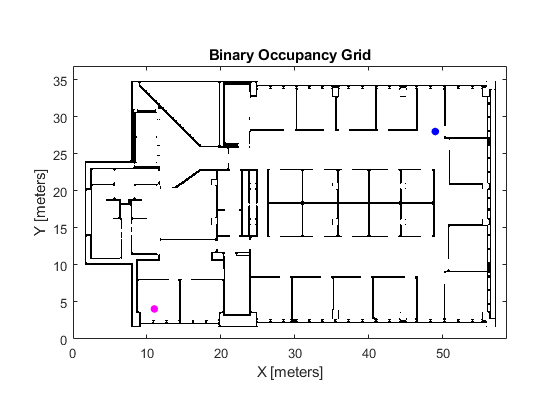

% Cargar mapa de la oficina y mostrarlo
clear; close all; clc;
img = imread('floorplan_hw.png');
res = 20;        % 20 cells per meter
map = robotics.BinaryOccupancyGrid(~img, res);
map.show();
hold on;


% Definir pose actual del robot, pose goal u objectivo, y graficarlas
% también
w_xi_robot = [11 4];
w_xi_goal  = [49 28];
plot(w_xi_robot(1), w_xi_robot(2), 'o', 'Color', 'magenta', ...
    'MarkerSize', 5, 'MarkerFaceColor', 'magenta');

plot(w_xi_goal(1), w_xi_goal(2), 'o', 'Color', 'blue', ...
    'MarkerSize', 5, 'MarkerFaceColor', 'blue');

### Diseñar Global Planner

Crear una clase que se llame GridPlanner e implementar los siguientes métodos:

% Inicializar la clase 
mode = 'breadth';                  % este parámetro es opcional, pueden implementar el algoritmo que quieran o seleccionar entre varios

robotRadius = 0.25;
goalRadiusTolerance = 0.05;  
Paces= 10;

Paces = 10

Path found


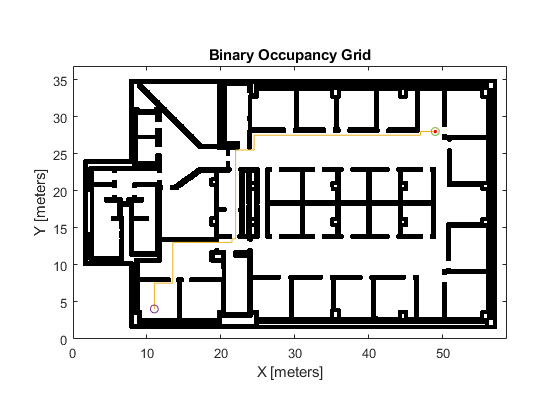

path =    11.0000    4.0000
   11.0000    4.5000
   11.0000    5.0000
   11.0000    5.5000
   11.0000    6.0000
   11.0000    6.5000
   11.0000    7.0000
   11.0000    7.5000
   11.5000    7.5000
   12.0000    7.5000


GridPlanner = gridPlanner(mode, robotRadius, goalRadiusTolerance);

% Cargar el mapa de navegación
GridPlanner.loadMap(map);



% Encontrar el camino midiendo el tiempo que se demoró, se pasa como entrada la pose 
% completa pero como es un robot diferencial no hay que tener en cuenta la
% orientación del robot en el planificador:
tic;
[path] = GridPlanner.plan(w_xi_robot, w_xi_goal,Paces)

toc;

Elapsed time is 14.090393 seconds.


% Graficar el camino encontrado y el mapa 
% Mostrar el mapa y el path encontrado.
% Si no existe camino posible, path debe ser [nan, nan]


## Cosas para tener en cuenta:

- Pueden implementar el módo de grid search que quieran.

- El planificador debe tener en cuenta el radio del robot. Vimos en clase como hacer esto.  

- Mostrar el ejemplo con al menos tres casos diferentes de pose del robot y pose de goal. 

- El tiempo de ejecución es solo didactico, no influye en la evaluación. 

- Seguramente van a tener que usar métodos de la clase de Binary Occupancy Grid (sobre todo transformaciónes de world a grid, etc)

- Por favor el código con buenos comentarios, así entiendo que hicieron.